**Loetakse sisse sobiv ajapiirkond andmeid**

clear;
close all;
warning('off','all')

directory = 'data/';
files_folders = dir(directory);
files = files_folders(~([files_folders.isdir])); 
num_files = length(files);

i = 1;
while(i <= num_files)
      disp(files(i).name)
      i = i + 1;
end

maindata.csv
metadata.csv
rawdata_2020-05-29_14-10-26.csv
rawdata_2020-05-29_14-10-37.csv
rawdata_2020-05-29_14-10-47.csv
rawdata_2020-05-29_14-10-57.csv
rawdata_2020-05-29_14-11-07.csv
rawdata_2020-05-29_14-11-18.csv
rawdata_2020-06-05_12-37-17.csv



date_str = input("Sisesta algusaeg (2020-05-29_14-10-26): ", 's');

i = 1;
while(i <= num_files)
      filename = files(i).name;
      if contains(filename, date_str) == true
          correct_filename = filename;
          disp("Valitud andmehulk: " + correct_filename)
      end
      i = i + 1;
end

rawdata = readtable(strcat(directory,correct_filename), "PreserveVariableNames",false);

Unrecognized function or variable 'correct_filename'.

**Demonteeritakse CSV fail Matlabile sobivateks maatriksiteks**

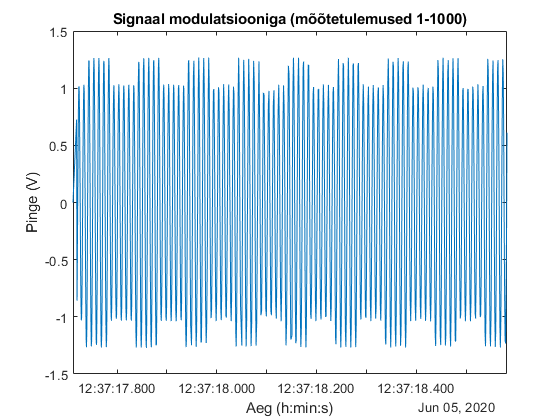

voltage = rawdata(:, 3);
voltage = voltage{:, :};
time = rawdata(:, 2);
time = time{:, :};

figure;
plot(time(1:1000), voltage(1:1000))
title('Signaal modulatsiooniga (mõõtetulemused 1-1000)')
xlabel('Aeg (h:min:s)')
ylabel('Pinge (V)')

**Leitakse terve signaali sageduste spekter kasutades FFT teisendust**

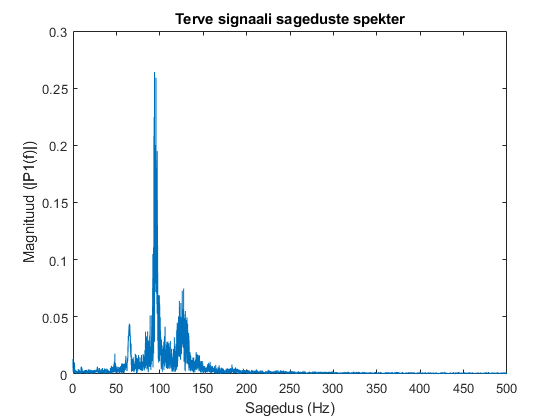

T = 0.001;
Fs = 1/T;   
L = length(voltage);
t = (0:L-1)*T;
f = Fs*(0:(L/2))/L;

fft_volt = fft(voltage);
P2 = abs(fft_volt)/L;
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

figure;
plot(f,P1) 
title('Terve signaali sageduste spekter')
xlabel('Sagedus (Hz)')
ylabel('Magnituud (|P1(f)|)')

**Leiatakse signaali nullpunktid, et leida keskmist mõõtetulemuste arvu ühe perioodi kohta, kasutades "zero-crossing" meetodit**

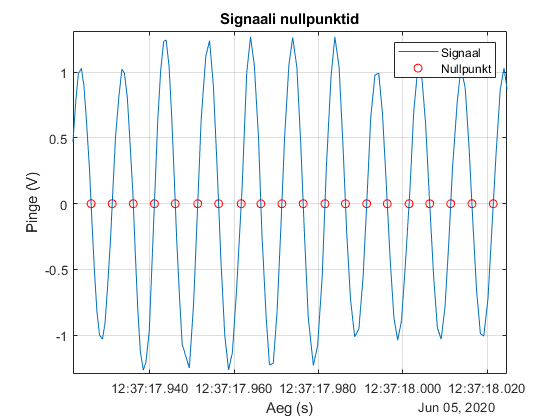

UpZCi = @(v) find(v(1:end-1) <= 0 & v(2:end) > 0);
DownZCi = @(v) find(v(1:end-1) >= 0 & v(2:end) < 0);
ZeroX = @(x0,y0,x1,y1) x0 - (y0.*(x0 - x1))./(y0 - y1);

ZXi = sort([UpZCi(voltage'),DownZCi(voltage')]);
ZX = ZeroX(time(ZXi),voltage(ZXi),time(ZXi+1),voltage(ZXi+1));

if voltage(end)==0
    ZX(end+1) = t(end);
end

figure;
plot(time, voltage)
hold on;
plot(ZX,zeros(1,length(ZX)),'ro')
grid on;
legend('Signaal', 'Nullpunkt')
title('Signaali nullpunktid')
xlabel('Aeg (s)')
ylabel('Pinge (V)')

**Kasutatakse "wavelet" funktsiooni, et eemaldada peamised sagedused ja jätta alles ainult signaalid, mis on väga väikese osakaaluga e müra signaal**

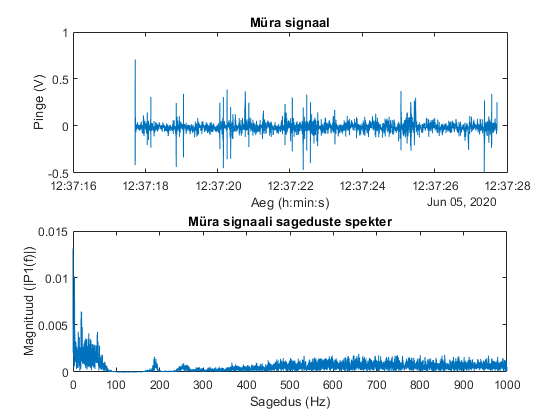

levelForReconstruction = [true, false, false, false, true, true, true, true, true, true, true, true, true, true];
wt = modwt(voltage, 'sym4', 13);
mra = modwtmra(wt, 'sym4');
voltage1 = sum(mra(levelForReconstruction,:),1);

T = 0.0005;
Fs = 1/T;   
L = length(voltage1);
t = (0:L-1)*T;
f = Fs*(0:(L/2))/L;

fft_volt1 = fft(voltage1);
P2 = abs(fft_volt1)/L;
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

figure;
subplot(2,1,1)
plot(time, voltage1)
title("Müra signaal")
ylabel("Pinge (V)")
xlabel('Aeg (h:min:s)')
subplot(2,1,2)
plot(f, P1)
title('Müra signaali sageduste spekter')
xlabel("Sagedus (Hz)")
ylabel("Magnituud (|P1(f)|)")

**Leitakse iga perioodi pinge RMS väärtus ja sageduste spekter ja võrreldakse neid, et leida seoseid RMS väärtuse muutumisega teatud ajahetkel ning samal ajal sageduse muutumist**

p = 15; % Perioodide pikkus
q = int64(height(rawdata)/p)-10; %10; % Mõõdetavate perioodide arv
m = 20; % Esimese perioodi esimene mõõtetulemus
n = 35; % Esimese perioodi viimane mõõtetulemus

rms_volt = zeros(1, q);
periods = zeros(1, q);
fft_total = zeros(q, 8); % FFT pikkus (varieerub vastavalt perioodi pikkusele)

for k = 1:q
    voltage_ind = voltage(m:n);
    
    periods(k) = k;
    rms_volt_ind = sqrt((sum(voltage_ind.^2))/length(voltage_ind));
    rms_volt(k) = rms_volt_ind;
    
    T_ind = 0.001;
    Fs_ind = 1/T_ind;
    L_ind = p;
    t_ind = (0:L_ind-1)*T_ind;
    f_ind = Fs_ind*(0:(L_ind/2))/L_ind;
    
    fft_volt_ind = fft(voltage_ind);
    P2_ind = abs(fft_volt_ind)/L_ind;
    P1_ind = P2_ind(1:L_ind/2+1);
    P1_ind(2:end-1) = 2*P1_ind(2:end-1);
    fft_total(k, :) = P1_ind';
    
    m=n;
    n=n + p; % Lisatakse mõõtepikkus
end

**Luuakse maatriksid perioodide, pinge RMS, FFT väärtuste ja sageduste hoiustamiseks/salvestamiseks**

maindata = zeros(q, 23);
maindata(1:q, 1) = periods';
maindata(1:q, 2) = rms_volt';
maindata(:, 3:10) = fft_total;

metadata = zeros(5, 11);
metadata(1, 1) = T_ind;
metadata(2, 1) = Fs_ind;
metadata(3, 1) = L_ind;
metadata(4, 1:8) = f_ind;

csvwrite("data\maindata.csv", maindata);
csvwrite("data\metadata.csv", metadata);

**Luuakse pinge RMS ja FFT tulemuste graafik**

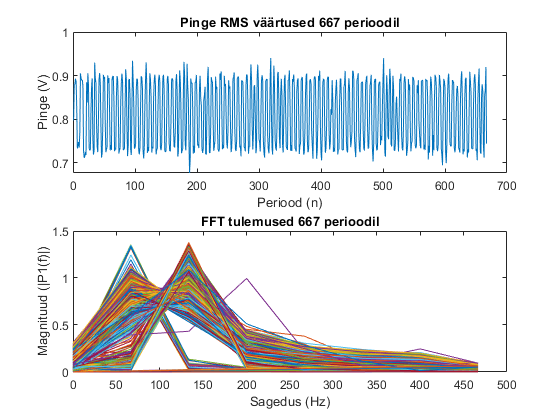

figure;
subplot(2,1,1)
plot(maindata(:, 1), maindata(:, 2))
title("Pinge RMS väärtused " + num2str(length(periods)) + " perioodil")
ylabel("Pinge (V)")
xlabel("Periood (n)")
subplot(2,1,2)
plot(metadata(4, 1:11), maindata(:, 3:13))
title("FFT tulemused " + num2str(length(periods)) + " perioodil")
xlabel("Sagedus (Hz)")
ylabel("Magnituud (|P1(f)|)")